# Angewandte Mathematik (CE/ET-M)

Hausarbeit 1. Prüfungszeitraum - Zeitaufgelöste Photolumineszenz

Bearbeiter A = Fabian Rod; Bearbeiter B = Lukas Mirow

Berlin den 26.07.2020 

## 1 Einleitung

Die folgende Arbeit beschäftigt sich mit der Anregung von zeitaufgelösten Photoluminiszenz-Spektren. Material wird mit einem Laser angeregt und das entstehende Licht in Abhängigkeit von der Zeit gemessen. Um wichtige Rückschlüsse zu ziehen bedarf es einer vorherigen Simulation der Dynamiken im Halbleiter. Diese Arbeit wird die Grundlagen einer solchen Simulation entwickeln.

## 2 Finite Differenzen der stationären Gleichung - Bearbeiter_in A

### 2.1 Lineare stationäre Gleichung

#### zu 2.1.1 Vorgehensweise zur Entwicklung des Gleichungssystems

In der dem Auszug aus Atkinson_Han_Elementary_Numercial_Analysis_2004_Auszug [1] wird beschrieben wie sich mit der "Finiten Difference Methode" Zweipunktgrenzwert Probleme lösen lassen. Dafür wird mit den Formeln aus [1]-(8.126 und 8.127) die Funktion aus (8.125) an y'' approximiert um eine Näherung der Lösung zu erhalten. Anschließend werden die Grenzwerte eingesetzt und für ein geeignetes i bestimmt. Das Ergebnis aus den beiden Grenzwerten und den inneren Knoten wird dann in einem System Ay=b aufgestellt. Wobei A die Koeffizenten Matrix darstellt und b die rechte Seite der des Gleichungssystems. Wichtig zu bemerken ist, dass die rechte Seite natürlich keine Abhängikeit von y enthalten soll.

$D\frac{\delta^2 u}{\delta z^2 }-ku=-s{\left(z\right)}\;\;\;\;,0<z<d,\;\;k=k_1 +k_2 N_D$     (1)

Diese prinzip lässt sich nun wie folgt bei dem vorliegenden Problem anwenden. Die in (1) gegebene Formel wird an $\ddot{u} \left(z\right)$approximiert. Dafür wird es von der Konstante D befreit und dann entsprechend der veränderten Formel aus [1]-(8.126 und 8.127) ersetzt. Wir haben nun eine allgemeine Form für das Gleichungssystem, was den inneren Knoten entspricht. Als nächstes werden entsprechend der folgenden Aufgabenstellungen die Randbedingungen (5) approximiert und für ein geeignetes i = 0,1,...N eingesetzte. D.h. in unserem Fall für i= 0 für die linke Grenze und i=N für die rechte Grenze.

Nun besitzten wir ein Gleichungssystem, welches  durch Anpassung der Granularität mit  $0\le i\le N$ein hinreichend genaue Lösung aufstellen lässt.

#### zu 2.1.2 Herleitung der Gleichung nach [1] - 8.8

Entsprechend [1]-(8.128) wird unser Gleichungssystem aufgestellt. Nach Umformung lässt sich für $\textrm{\"u}\left(z\right)$die finite Differnezmethode mit der approximation anwenden. wir erhalten eine allgemeine Gleichung (3) die wir noch weiter verinfachen können (4).


$$\begin{array}{l}
D\frac{\delta^2 u}{\delta z^2 }-ku=-s{\left(z\right)}\;\;\;\;,0<z<d,\;\;k=k_1 +k_2 N_D \;\;\;\;\;\left(1\right)\\
\left\lbrace \begin{array}{ll}
\textrm{D\"u}\left(z\right)-\textrm{ku}=-s\left(z\right) & \\
\textrm{Du}̇\left(z\right)\left(0\right)=S_R \left(0\right)\;\;\;\left(2\ldotp 1\right), & \textrm{Du}̇\left(z\right)\left(d\right)=S_R u\left(d\right)\;\;\left(2\ldotp 2\right)
\end{array}\;\;\;\;\;\right.\\
\textrm{\"u}\left(z\right)-\frac{\textrm{ku}}{D}=-\frac{s\left(z\right)}{D}\\
\frac{u_{i+1} -{2u}_i +u_{i-1} }{h^2 }-\frac{ku_i }{D}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\frac{s_i }{D}\;\;\left(3\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\begin{array}{l}
s\left(z_i \right)=s_i \\
u\left(z_i \right)=u_i 
\end{array}
\end{array}$$



$$\begin{array}{l}
\frac{u_{i+1} }{h^2 }+\frac{u_{i-1} }{h^2 }-\left(\frac{{2u}_i }{h^2 }+\frac{{\textrm{ku}}_i }{D}\right)\;\;\;\;\;\;\;\;\;\;\;\;=-\frac{s_i }{D}\\
\frac{u_{i+1} }{h^2 }+\frac{u_{i-1} }{h^2 }-h^2 \left(\frac{{2Du_i +{\textrm{kh}}^2 u}_i }{D}\right)=-\frac{s_i }{D}\\
u_{i+1} +u_{i-1} -\left(\frac{2D+h^2 k}{D}\right)u_i \;\;\;\;\;\;\;\;=-\frac{s_i h^2 }{D}\;\;\;\;\;\;\left(4\right)
\end{array}$$


#### zu 2.1.3 Approximation der Randbedingungen

Als nächstes werden die Randgebiete (2.1 und 2.2) mit $\dot{u} \left(z\right)$ebenfals approximiert und für i=0 und i=N in der Gleichung (4) eingesetzt.

 $\begin{array}{l}
\frac{u_1 -u_{-1} }{2h}=\frac{S_L u_0 }{D}\\
u_1 -u_{-1} =\frac{2hS_L u_0 }{D}\\
u_{-1} =-\frac{2hS_L u_0 }{D}+u_1 
\end{array}$     (2.1 an $\textrm{\"u}\left(z\right)$ approximiert mit i=0)               $\begin{array}{l}
\frac{u_{N+1} -u_{N-1} }{2h}=-\frac{S_R {\;u}_N }{D}\\
u_{N+1} -u_{N-1} =-\frac{2h\;S_R \;u_N }{D}\\
u_{N+1} =-\frac{2h{\;S}_R \;u_N }{D}+u_{N-1} 
\end{array}$     (2.2 an $\textrm{\"u}\left(z\right)$ approximiert mit i=N)   

Man erhält die beiden Gleichungen für die Randbedingungen an der linken Seite und rechten Seite. In unser Matrix entspricht dies die 1 Zeile (i=0) und die letzte Zeile(i=N).


$$\begin{array}{l}
i=0\\
u_1 +u_{-1} -\left(\frac{2D+{\textrm{kh}}^2 }{D}\right)u_0 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\frac{S_0 h^2 }{D}\\
u_1 +u_1 -\left(\frac{2hS_L }{D}\right)u_0 -\left(\frac{2D+{\textrm{kh}}^2 }{D}\right)u_0 =-\frac{S_0 h^2 }{D}\\
2u_1 -\left(\frac{2hS_L +2D+{\textrm{kh}}^2 }{D}\right)u_0 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\frac{S_0 h^2 }{D}\\
2u_1 -2h\left(\frac{S_L }{D}+\frac{1}{h}+\frac{\textrm{hk}}{2D}\right)u_0 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\frac{S_0 h^2 }{D}
\end{array}$$
                                        
$$\begin{array}{l}
i=N\\
u_{N+1} +u_{N-1} -\left(\frac{2D+{\textrm{kh}}^2 }{D}\right)u_N =-\frac{S_N h^2 }{D}\\
u_{N-1} +u_{N-1} -\left(\frac{2hS_R }{D}\right)u_N -\left(\frac{2D+{\textrm{kh}}^2 }{D}\right)u_N =-\frac{S_N h^2 }{D}\\
2u_{N-1} -\left(\frac{2hS_R +2D+{\textrm{kh}}^2 }{D}\right)u_N =-\frac{S_N h^2 }{D}\\
2u_{N-1} -2h\left(\frac{S_R }{D}+\frac{1}{h}+\frac{\textrm{hk}}{2D}\right)u_N =-\frac{S_N h^2 }{D}
\end{array}$$


#### zu 2.1.4 Lineares Gleichungssystem

Nun können wir ein geeignetes Gleichungssystem nach $\textrm{Au}=b,u=\left\lbrack u_i \right\rbrack ,\;b=\left\lbrack b_i \right\rbrack$aufstellen. D.h. wir setzen in unsere Gleichung (4) für i=1 und i=N-1 ein und erkennen den linearen Zusammenhang aus dem sich der Bereich der inneren Knoten einfach aufstellen lässt.


$$\begin{array}{l}
i=1\\
u_{i+1} +u_{i-1} -\left(\frac{2D+h^2 k}{D}\right)u_i \;\;\;=-\frac{s_i h^2 }{D}\\
u_2 +u_0 -\left(\frac{2D+h^2 k}{D}\right)u_1 \;\;\;\;\;\;\;\;\;=-\frac{s_1 h^2 }{D}\\
u_0 -\left(\frac{2D+h^2 k}{D}\right)u_1 +u_2 \;\;\;\;\;\;\;\;\;=-\frac{s_1 h^2 }{D}
\end{array}$$
                     
$$\begin{array}{l}
i=N-1\\
u_{i+1} +u_{i-1} -\left(\frac{2D+h^2 k}{D}\right)u_i \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\frac{s_i h^2 }{D}\\
u_N +u_{N-2} -\left(\frac{2D+h^2 k}{D}\right)u_{N-1} \;\;\;\;\;\;\;\;\;=-\frac{s_N h^2 }{D}\\
u_{N-2} -\left(\frac{2D+h^2 k}{D}\right)u_{N-1} +u_N \;\;\;\;\;\;\;\;\;=-\frac{s_1 h^2 }{D}
\end{array}$$


Es ergibt sich mit den Gleichungen die Koefizientenmatrix A. Die rechte Seite b lässt sich entsprechend der rechten Seite der Gleichungen auch zusammenstellen. WICHTIG die in der Matrix A erkennbaren $u_i$ dienen rein der Verständlichkeit der Spaltenzugehörigkeit, tauchen aber in dieser Sparse Matrix als Variablen NICHT auf. Jedoch didaktisch an diesem Punkt der Arbeit bieten Sie den Vorteil zu erkennen, wie sich das Gleichungssystem entwickelt.

$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;A\\
\left\lbrack \begin{array}{cccccc}
-2h\left(\frac{1}{h}+\frac{S_L }{D}+\frac{\textrm{hk}}{2D}\right)u_0  & 2u_1  & 0 & 0 & 0 & 0\\
1u_0  & -\left(\frac{2D+h^2 k}{D}\right)u_1  & 1u_2  & 0 & 0 & 0\\
0 & 1u_1  & -\left(\frac{2D+h^2 k}{D}\right)u_2  & 1u_3  & 0 & 0\\
 & 0 & 1u_{i-1}  & -\left(\frac{2D+h^2 k}{D}\right)u_i  & 1u_{i+1}  & 0\\
 &  &  & 1u_{N-2}  & -\left(\frac{2D+h^2 k}{D}\right)u_{N-1}  & 1u_N \\
 &  &  &  & 2u_{N-1}  & -2h\left(\frac{S_R }{D}+\frac{1}{h}+\frac{\textrm{hk}}{2D}\right)u_N 
\end{array}\right\rbrack 
\end{array}$*$\begin{array}{l}
\;\;\;\;\;\;u\\
\left\lbrack \begin{array}{c}
u_0 \\
u_1 \\
u_2 \\
u_i \\
u_{N-1} \\
u_N 
\end{array}\right\rbrack 
\end{array}$=$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;B\\
\left\lbrack \begin{array}{c}
-\frac{s_0 h^2 }{D}\\
-\frac{s_1 h^2 }{D}\\
-\frac{s_2 h^2 }{D}\\
-\frac{s_i h^2 }{D}\\
-\frac{s_{N-1} h^2 }{D}\\
-\frac{s_N h^2 }{D}
\end{array}\right\rbrack 
\end{array}$

#### zu 2.1.5 Routine A = fd_lin_matrix(N)

Die Implementierung war straight forward. N bestimmt die Schrittweite h. Die Grenzen werden fest definiert und die inneren Knoten entsprechen einem Muster.

disp("zu 2.1.5")

zu 2.1.5


disp("Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.")

Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.


global P;
P(:,1)= parametervektor;
A = fd_lin_matrix(6);
disp(A);

   (1,1)      -2.1250
   (2,1)       1.0000
   (1,2)       2.0000
   (2,2)      -2.0917
   (3,2)       1.0000
   (2,3)       1.0000
   (3,3)      -2.0917
   (4,3)       1.0000
   (3,4)       1.0000
   (4,4)      -2.0917
   (5,4)       1.0000
   (4,5)       1.0000
   (5,5)      -2.0917
   (6,5)       1.0000
   (5,6)       1.0000
   (6,6)      -2.0917
   (7,6)       2.0000
   (6,7)       1.0000
   (7,7)    -335.4250



#### zu 2.1.6 Routine [z,u] = stationaer_lin(s,N)

Auch hier ist die Implementierung recht einfach. Wir nutzen die Funktion fd_lin_matrix() um die Matrix zu erhalten. Die rechte Seite lässt sich recht einfach erstellen, wobei hier noch mit der Schrittweite h der z-Vektor gebaut werden muss um dann in der Abhängikeit s(z) eingesetzt zu werden. u = A\b löst dann mein Gleichunssystem.

disp("zu 2.1.6")

zu 2.1.6


disp("Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.")

Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.


P(:,1)= parametervektor;
[z,uz]=stationaer_lin(@s,6);
disp("z =");

z =


disp(z);

         0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000



disp("u = ");

u = 


disp(uz);

    3.0471
    2.8209
    2.3478
    1.7834
    1.1965
    0.6065
    0.0037



#### zu 2.1.7 Testen der Routinen

Es werden geeignete Konstanten genommen und sich ein u(z) ausgedacht, welches abgeleitet wird. Dadurch lässt sich S(z) bestimmen und auch die Konstanten SL und SR aus den Randwerten.


$$\begin{array}{l}
d=3\\
D=2\\
K_1 =4\;\\
K_2 =2\\
N_D =0
\end{array}$$
        
$$\begin{array}{l}
\textrm{Funktion}\;u\left(z\right)\textrm{ausdenken}\\
u\left(z\right)=5z^4 +2z+5\\
\dot{u} \left(z\right)=20z^3 +2\\
\ddot{u} \left(z\right)=60z^2 
\end{array}$$
        
$$\begin{array}{l}
\textrm{Gleichung}\;\textrm{nach}\;S\left(z\right)\;\textrm{lösen}\\
D\ddot{\mathrm{u}} \left(z\right)-k\left(u\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-S\left(z\right)\\
2\left(60z^2 \right)-4\left(5z^4 +2z+5\right)\;=-S\left(z\right)\\
120z^2 -20z^4 -8z-20\;\;\;\;\;\;=-S\left(z\right)\\
20z^4 -120z^2 +8z-20\;\;\;\;\;\;=S\left(z\right)
\end{array}$$
   

Randwerte aufstellen und Funktionen einsetzen. Wir erhalten $S_L$ und $S_R$


$$\begin{array}{l}
D\dot{\mathrm{u}} \left(z\right)\left(0\right)\;\;\;\;=S_L u\left(z\right)\left(0\right)\\
2\left(20z^3 +2\right)=S_L \left(5z^4 +2z+5\right)\;\;\;\;\;\;\;\;\;\left(z=0\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;4={5S}_L \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{4}{5}=S_L 
\end{array}$$
            
$$\begin{array}{l}
D\dot{\mathrm{u}} \left(z\right)\left(d\right)\;\;\;\;\;\;\;\;\;\;\;={-S}_R u\left(z\right)\left(d\right)\\
2\left(20z^3 +2\right)\;\;\;\;\;\;\;={-S}_R \left(5z^4 +2z+5\right)\\
-\frac{40z^3 +4}{5z^4 +2z+5}\;=S_R \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(z=3\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\frac{271}{104}\;=S_R 
\end{array}$$


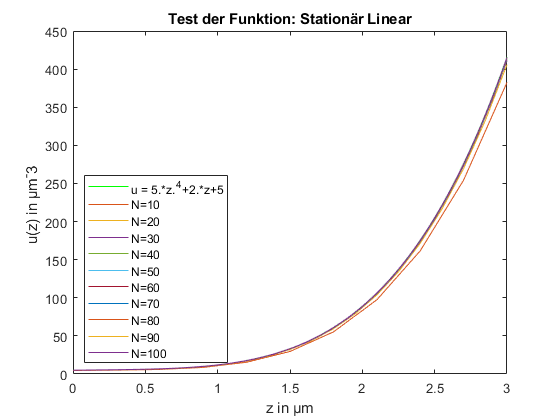

P = ones(8,1);

%% Parameter [1-8]
d       = 3;                %µm
D       = 2;                %µm^2/µs
k1      = 4;                %1/µs
k2      = 2;                %µm^3/µs
ND      = 0;                %1/µm^3
SL      = 4/5;              %µm/µs
SR      = -271/104;         %µm/µs
alpha   = 10;               %µm

P(1,1) = d;
P(2,1) = D;
P(3,1) = k1;
P(4,1) = k2;
P(5,1) = ND;
P(6,1) = SL;
P(7,1) = SR;
P(8,1) = alpha;  

%% Berechnungen

z = (0:0.001:d)';
uz = u(z); 

legendCell = strcat('N=',string(num2cell(0:10:100)));
legendCell(1,1) = 'u = 5.*z.^4+2.*z+5';
 
plot(z,uz,'g');
title('Test der Funktion: Stationär Linear');
xlabel("z in µm" );
ylabel("u(z) in µm^-3 ");

hold on;

for N=10:10:100
    [zN,uN] = stationaer_lin(@s_test_lin,N);
    plot(zN,uN,'MarkerIndices',[1 2 3]);
end

legend(legendCell,'Location','southwest');
hold off;

Man erkennt gut, dass mitsteigendem N sich unsere Finite Differenzen Methode der Orginalfunktion u annähert. Und somit unsere Berechnungen offensichtlich funktionieren.

#### zu 2.1.8 Bestimmung eines hinreichenden N für S0=1e+2,S0=1e+3,S0=1e+4

Die einzelnen Fälle sind in s, s3 und s4 gespeichert. Der relative Fehler entspricht 0.001. Da wir nicht die genaue Lösung kennen gehen wir davon aus, dass wir mit einem hohen N von 10000 eine sehr gute Annäherung bekommen mit minimalen Fehler kleiner als 0.001. Dieses Ergebnis wird nun mit den verschiedenen N verglichen um herauszubekommen ab wann die Größe N ausreichend ist.

Die Funktion bestNLinMod() ist eine Anpassung an den veränderten Anforderungen eine näherungsweise Lösung zu bekommen. Deshalb entspricht die Schrittweite und immer dem Verhältnis der zu prüfenden Größe N. D.h. bei einem N=10 wird die Referenzlösung N=10000 durch 1000 geteilt und entsprechende Werte 0,1000,2000,...,N zum Vergleich herangezogen.

disp("zu 2.1.8");

zu 2.1.8


disp("Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.")

Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.


P(:,1)= parametervektor;
PN = bestNLinMOD();
disp("Die Funktion gibt einen Spaltenvektor für S0=1e+2,S0=1e+3,S0=1e+4 aus mit den entsprechenden besten N Werten")

Die Funktion gibt einen Spaltenvektor für S0=1e+2,S0=1e+3,S0=1e+4 aus mit den entsprechenden besten N Werten


disp("PN = ");

PN = 


disp(PN);

    50
    50
    50



Man sieht das sich in einem linearen Gleichungssystem mit Erhöhung von S0 das System nur höher skaliert aber kein Einfluss auf den relativen Fehler gibt.

### 2.2 Nichtlineare stationäre Gleichung

Nun wird unsere lineare stationäre Gleichung um den quadratischen Termin erweitert und neu betrachtet. Es werden dafür die Formel (5) und mit den gleichen Randbedingungen (2.1 und 2.2) verwendet


$$\begin{array}{l}
D\frac{\delta^2 u}{\delta z^2 }-\left(k_1 +k_2 N_D \right)u-k_2 u^2 =-s\left(z\right)\;\;\;\;\;0<z<d,\;\;k=k_1 +k_2 N_D \\
\left\lbrace \begin{array}{ll}
\textrm{D\"u}\left(z\right)-\textrm{ku}-k_2 u^2 =-s\left(z\right)\;\;\;\;\;\;\;\left(5\right) & \\
\textrm{Du}̇\left(z\right)\left(0\right)=S_L u\left(0\right)\;,\;\left(2\ldotp 1\right) & \textrm{Du}̇\left(z\right)\left(d\right)=S_R u\left(d\right)\;\;\left(2\ldotp 2\right)
\end{array}\right.
\end{array}$$


#### zu 2.2.1 Herleitung der Nichtlinearen Gleichung

Als erstes wird die Gleichung (5) für die Approximation mit $\ddot{u} \left(z\right)$umgestellt


$$\begin{array}{l}
D\ddot{u} \left(z\right)-\textrm{ku}-k_2 u^2 =-S\left(z\right)\\
\ddot{u} \left(z\right)-\frac{\textrm{ku}}{D}-\frac{k_2 u^2 }{D}=-\frac{S\left(z\right)}{D}
\end{array}$$


Dann wird analog zu 2.1.2 approximiert und umgestellt. So dass sich die allgemeine Formel (7) ergibt.


$$\begin{array}{l}
\frac{u_{i+1} -2u_i +u_{i-1} }{h^2 }-\frac{ku_i }{D}-\frac{k_2 u_i^2 }{D}=-\frac{S_i }{D}\\
\frac{u_{i+1} }{h^2 }-\frac{{2u}_i }{h^2 }+\frac{u_{i-1} }{h^2 }-\frac{ku_i }{D}-\frac{k_2 u_i^2 }{D}=-\frac{S_i }{D}\\
\frac{u_{i+1} }{h^2 }+\frac{u_{i-1} }{h^2 }-\left(\frac{2}{h^2 }+\frac{k}{D}\right)u_i -\frac{k_2 u_i^2 }{D}=-\frac{S_i }{D}\\
u_{i+1} +u_{i-1} -\left(2+\frac{{\textrm{kh}}^2 }{D}\right)u_i -\left(\frac{k_2 h^2 }{D}\right)u_i^2 =-\frac{S_i h^2 }{D}\;\;\;\left(7\right)
\end{array}$$


Nun können wir mit den Randbedingungen entsprechend verfahren und sie nach $u_{-1} \;\textrm{und}\;u_{N+1}$umstellen. Eingesetz in (7) für i=0 und i=N 

ergeben sich die neuen Randgleichungen (8.1) (8.2).


$$\begin{array}{l}
\frac{u_1 -u_{-1} }{2h}=\frac{S_L u_0 }{D}\\
u_1 -u_{-1} =\frac{2hS_L u_0 }{D}\\
u_{-1} =-\frac{2hS_L u_0 }{D}+u_1 
\end{array}$$
                    
$$\begin{array}{l}
\frac{u_{N+1} -u_{N-1} }{2h}=-\frac{S_R {\;u}_N }{D}\\
u_{N+1} -u_{N-1} =-\frac{2h\;S_R \;u_N }{D}\\
u_{N+1} =-\frac{2h{\;S}_R \;u_N }{D}+u_{N-1} 
\end{array}$$



$$\begin{array}{l}
i=0\\
u_1 +u_{-1} -\left(2+\frac{{\textrm{kh}}^2 }{D}\right)u_0 -\left(\frac{k_2 h^2 }{D}\right)u_0^2 =-\frac{S_0 h^2 }{D}\\
-\frac{2hS_L u_0 }{D}+u_1 +u_1 -\left(2+\frac{{\textrm{kh}}^2 }{D}\right)u_0 -\left(\frac{k_2 h^2 }{D}\right)u_0^2 =-\frac{S_0 h^2 }{D}\\
-\left(\frac{2hS_L }{D}+2+\frac{{\textrm{kh}}^2 }{D}\right)u_0 -\left(\frac{k_2 h^2 }{D}\right)u_0^2 +{2u}_1 =-\frac{S_0 h^2 }{D}\;\left(8\ldotp 1\right)
\end{array}$$
         
$$\begin{array}{l}
i=N\\
u_{N+1} +u_{N-1} -\left(2+\frac{{\textrm{kh}}^2 }{D}\right)u_N -\left(\frac{k_2 h^2 }{D}\right)u_N^2 =-\frac{S_N h^2 }{D}\\
-\frac{2h{\;S}_R \;u_N }{D}+{2u}_{N-1} -\left(2+\frac{{\textrm{kh}}^2 }{D}\right)u_N -\left(\frac{k_2 h^2 }{D}\right)u_N^2 =-\frac{S_N h^2 }{D}\\
{2u}_{N-1} -\left(\frac{2h{\;S}_R }{D}+2+\frac{{\textrm{kh}}^2 }{D}\right)u_N -\left(\frac{k_2 h^2 }{D}\right)u_N^2 =-\frac{S_N h^2 }{D}\;\left(8\ldotp 2\right)
\end{array}$$


Wir schauen uns das System an 2 weiteren Knoten an und können dann besser generalisieren.


$$\begin{array}{l}
i=1\\
u_2 +u_0 -\left(2+\frac{{\textrm{kh}}^2 }{D}\right)u_1 -\left(\frac{k_2 h^2 }{D}\right)u_1^2 =-\frac{S_1 h^2 }{D}\\
u_0 -\left(2+\frac{{\textrm{kh}}^2 }{D}\right)u_1 -\left(\frac{k_2 h^2 }{D}\right)u_1^2 +u_2 =-\frac{S_1 h^2 }{D}
\end{array}$$
        
$$\begin{array}{l}
i=N-1\\
u_N +u_{N-2} -\left(2+\frac{{\textrm{kh}}^2 }{D}\right)u_{N-1} -\left(\frac{k_2 h^2 }{D}\right)u_{N-1}^2 =-\frac{S_{N-1} h^2 }{D}\\
u_{N-2} -\left(2+\frac{{\textrm{kh}}^2 }{D}\right)u_{N-1} -\left(\frac{k_2 h^2 }{D}\right)u_{N-1}^2 +u_N =-\frac{S_{N-1} h^2 }{D}
\end{array}$$


Damit sich unser F(u) übersichtlich bleibt entscheiden wir uns mit Variablen zu arbeiten:

$L=\frac{2hS_L }{D}+2+\frac{{\textrm{kh}}^2 }{D}$   , $b=\frac{k_2 h^2 }{D}$    , $c=2+\frac{{\textrm{kh}}^2 }{D}$$,\;R=\frac{2hS_R }{D}+2+\frac{{\textrm{kh}}^2 }{D}$ 

Daraus ergibt sich unser F in Abhängigkeit von u wie folgt:


$$\overset{F\left(u\right)}{\left\lbrack \begin{array}{c}
-\left(L\right)u_0 -\left(b\right)u_0^2 +2u_1 \\
1u_0 -\left(c\right)u_1 -\left(b\right)u_1^2 +1u_2 \\
1u_{i-1} -\left(c\right)u_i -\left(b\right)u_i^2 +1u_{i+1} \\
1u_{N-2} -\left(c\right)u_{N-1} -\left(b\right)u_{N-1}^2 +1u_N \\
2u_{N-1} -\left(R\right)u_N -\left(b\right)u_N^2 
\end{array}\right\rbrack } =\overset{b}{\left\lbrack \begin{array}{c}
-\frac{S_0 h^2 }{D}\\
-\frac{S_1 h^2 }{D}\\
-\frac{S_i h^2 }{D}\\
-\frac{S_{N-1} h^2 }{D}\\
-\frac{S_N h^2 }{D}
\end{array}\right\rbrack }$$
   

Die rechte Seite hat sich dabei nicht verändert. Unser F(u) besitzt wieder 2 Gleichungen für die Grenzwerte und lässt sich ansonsten für die inneren Knoten generalisieren. 

#### zu 2.2.2 Routine F = fd_nonlin(u,N)

Im Unterschied zur eben aufgstellten Funktion wird die folgende Implementierung nicht mit einem Symbol in Matlab arbeiten, sondern einem Spaltenvektor für u(i). Dabei ist zu beachten, dass Zugriffe in Vektoren bei 1 anfangen. Entsprechend enthält der Wert u(1) den $u_0$ Wert usw.

disp("zu 2.2.2")

zu 2.2.2


disp("Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.")

Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.


P(:,1)= parametervektor;
F = fd_nonlin((1:10)',9);
disp("F = ");

F = 


disp(F);

   1.0e+03 *

    0.0019
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0002
   -0.0003
   -0.0003
   -0.0004
   -2.2246



#### zu 2.2.3 Berechnung der Jacobi-Matrix

Die Jacobi-Matrix ist eine partielle Ableitung der einzelnen Gleichungen (Zeilen) und der entsprechenden vorhanden Variablen (Spalten) und  ergibt sich wie folgt:


$$\overset{\textrm{DF}\left(u\right)}{\left\lbrack \begin{array}{cccccc}
-\left(L\right)-2\left(b\right)u_0  & 2 & 0 & 0 & 0 & 0\\
1 & -c-2\left(b\right)u_1  & 1 & 0 & 0 & 0\\
0 & 1 & -c-2\left(b\right)u_2  & 1 & 0 & 0\\
0 & 0 & 1 & -c-2\left(b\right)u_i  & 1 & 0\\
0 & 0 & 0 & 1 & -c-2\left(b\right)u_{N-1}  & 1\\
0 & 0 & 0 & 0 & 2 & -\left(R\right)-2\left(b\right)u_N 
\end{array}\right\rbrack }$$


#### zu 2.2.4 Routine J = fd_nonlin_jac(u,N)

Dies lässt sich in einer Implementierung recht einfach darstellen. Wir verwenden auch hier wieder eine Sparse-Matrix

disp("zu 2.2.4")

zu 2.2.4


disp("Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.")

Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.


P(:,1)= parametervektor;
J = fd_nonlin_jac((1:10)',9);
disp("J = ");

J = 


disp(J);

   (1,1)      -2.0630
   (2,1)       1.0000
   (1,2)       2.0000
   (2,2)      -2.0409
   (3,2)       1.0000
   (2,3)       1.0000
   (3,3)      -2.0410
   (4,3)       1.0000
   (3,4)       1.0000
   (4,4)      -2.0410
   (5,4)       1.0000
   (4,5)       1.0000
   (5,5)      -2.0411
   (6,5)       1.0000
   (5,6)       1.0000
   (6,6)      -2.0412
   (7,6)       1.0000
   (6,7)       1.0000
   (7,7)      -2.0413
   (8,7)       1.0000
   (7,8)       1.0000
   (8,8)      -2.0413
   (9,8)       1.0000
   (8,9)       1.0000
   (9,9)      -2.0414
  (10,9)       2.0000
   (9,10)      1.0000
  (10,10)   -224.2637



#### zu 2.2.5 Routine [z,u] = stationaer_nonlin(s,N,tol,nmax)

Um das Gleichungssystem zu lösen benötigen wir die Newton Funktion aus der Belgearbeit. Diese wurde in stationaer_nonlin integriert. Wichtig ist, dass wir mit fd_nonlin() und fd_nonlin_jac() unser F und Df bekommen. Aber unser F(u) ist nicht 0. D.h. wir müssen davon stets die rechte Seite b abziehen bevor wir weiterrechnen dürfen. Ansonsten enstehen keine weiteren Probleme.

disp("zu 2.1.5")

zu 2.1.5


disp("Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.")

Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.


P(:,1)= parametervektor;
[z,uz]=stationaer_nonlin(@s,6,1e-8,30);
disp("z =");

z =


disp(z);

         0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000



disp("u = ");

u = 


disp(uz);

    3.0435
    2.8175
    2.3449
    1.7812
    1.1951
    0.6058
    0.0037



#### zu 2.2.6 Testen der Routinen

Hier können wir die gleiche Funktion und Konstanten von 2.1.7 nehmen müssen nur die Gleichung S(z) mit dem quadratischen Term neu aufsetzen und lösen. Die Randwerte ändern sich nicht.


$$\begin{array}{l}
\textrm{Gleichung}\;\textrm{nach}\;S\left(z\right)\;\textrm{lösen}\\
D\ddot{\mathrm{u}} \left(z\right)-k\left(u\right)-k_2 {\left(u\right)}^2 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-S\left(z\right)\\
2\left(60z^2 \right)-4\left(5z^4 +2z+5\right)-2{\left(5z^4 +2z+5\right)}^{2\;\;\;} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-S\left(z\right)\\
120z^2 -20z^4 -8z-20-2\left(25z^8 +20z^5 +50z^4 +4z^2 +20z+25\right)\;\;\;\;=-S\left(z\right)\\
-120z^2 +20z^4 +8z+20+50z^8 +40z^5 +100z^4 +8z^2 +40z+50\;\;\;\;=S\left(z\right)\\
50z^8 +40z^5 +120z^4 -112z^2 +48z+70\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=S\left(z\right)
\end{array}$$


P = ones(8,1);

%% Parameter [1-8]
d       = 3;                %µm
D       = 2;                %µm^2/µs
k1      = 4;                %1/µs
k2      = 2;                %µm^3/µs
ND      = 0;                %1/µm^3
SL      = 4/5;              %µm/µs
SR      = -271/104;         %µm/µs
alpha   = 10;               %µm

P(1,1) = d;
P(2,1) = D;
P(3,1) = k1;
P(4,1) = k2;
P(5,1) = ND;
P(6,1) = SL;
P(7,1) = SR;
P(8,1) = alpha;  

%% Berechnungen

z = (0:0.001:d)';
uz = u(z); 

legendCell = strcat('N=',string(num2cell(0:10:100)));
legendCell(1,1) = 'u = 5.*z.^4+2.*z+5';
 
plot(z,uz,'g');
title('Test der Funktion: Stationär NonLinear');
xlabel("z in µm" );
ylabel("u(z) in µm^-3 ");

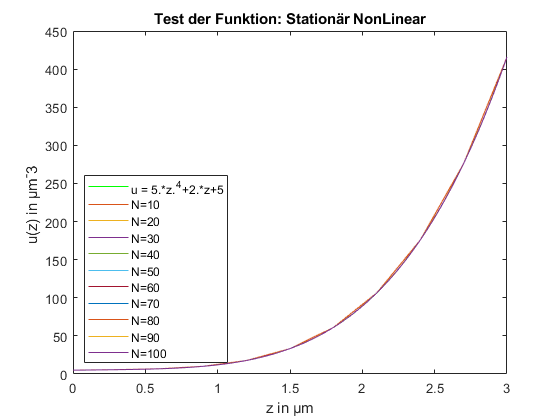



hold on;

for N=10:10:100
    [zN,uN] = stationaer_nonlin(@s_test_nonlin,N,1e-8,15);
    plot(zN,uN,'MarkerIndices',[1 2 3]);
end

legend(legendCell,'Location','southwest');
hold off;

Auch hier zeigt sich, dass unsere Funktionen funktionieren und sich in ihrem Ergebnis um die festgelegte Funktion u schmiegen. Beim heranzoomen erkennt man auch die steigende Genauigkeit bei Erhöhung von N.

#### zu 2.2.7 Bestimmung eines hinreichenden N für S0=1e+2,S0=1e+3,S0=1e+4

Die einzelnen Fälle sind in s, s3 und s4 gespeichert. Der relative Fehler entspricht 0.001. Wir nehmen nutzen hier als Grundlage die bestNLinMOD() Funktion und passen die Funktion auf nonLin an. Der Rest bleibt gleich.

disp("zu 2.1.7");

zu 2.1.7


disp("Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.")

Die Konstanten für die Lösungen stehen im Parametervektor und werden über die globale Variable P festgelegt! Darauf muss man achten, sonst besitzten sie keine Zuordnung.


P(:,1)= parametervektor;
PN = bestNNonLinMOD();
disp("Die Funktion gibt einen Spaltenvektor für S0=1e+2,S0=1e+3,S0=1e+4 aus mit den entsprechenden besten N Werten")

Die Funktion gibt einen Spaltenvektor für S0=1e+2,S0=1e+3,S0=1e+4 aus mit den entsprechenden besten N Werten


disp("PN = ");

PN = 


disp(PN);

    50
    50
    50



Leider zeigt sich hier bei Veränderung von S0 keine Veränderung in der Genauigkeit. Es ergibt sich für alle der gleiche beste N Wert bei entsprechendem relativen Fehler. Wenn man jedoch S0 noch höher als 1e+4 ansätzt entwickelt sich eine höhere Ungenauigkeit und wir benötigen größere N Werte. Dies hängt mit dem quadratischen Term zusammen.

## 3. Implizite Einschrittverfahren - Bearbeiter_in B

## `3.1 Entwicklung`

### `3.1.1 Differenzialgleichung`

`Differentialgleichungen heißen steif wenn bestimmte numerische Methoden nur bei ausreichend kleiner Schrittgröße h konvergieren.`

### `3.1.2 Implizite Euler-Verfahren & Implizite Trapezregel als Nullstellenproblem`

`Impliziter Euler:`


$$\begin{array}{l}
\;\;\;\;\;\;\;\;\;y{\;}^{\left(i+1\right)} =y{\;}^{\left(i\right)} +h\;f\left(t_{i+1} ,y^{\left(i+^{\left.\right)} \right)} \right)\\
\Leftrightarrow y{\;}^{\left(i\right)} +z=y{\;}^{\left(i\right)} +h\;f\left(t_{i+1} ,y{\;}^{\left(i\right)} +z\right)\\
\Leftrightarrow \;\;\;\;\;\;\;\;\;\;\;\;0=h\;f\left(t_{i+1} ,y^{\left(i\right)} +z\right)-z\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=F_{\textrm{euler}} \left(z\right)
\end{array}$$


`Implizite Trapezregel:`


$$\begin{array}{l}
\;\;\;\;\;\;\;\;\;y{\;}^{\left(i+1\right)} =y^{\left(i\right)} +\frac{h\;}{\;2}\;\left\lbrack f\left(t_i ,y{\;}^{\left(i\right)} \right)+f\left(t_{i+1} ,y^{\left(i+1\right)} \right)\right\rbrack \\
\Leftrightarrow y{\;}^{\left(i\right)} +z=y{\;}^{\left(i\right)} \frac{h}{2}\;\left\lbrack f\left(t_i ,y^{\left(i\right)} \right)+f\left(t_{i+1} ,y{\;}^{\left(i\right)} +z\right)\right\rbrack -z\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=F_{\mathrm{trapez}} \left(z\right)
\end{array}$$


### `3.1.3 Abhängikeit der Jacobi-Matrix von f bezüglich y`

Die Jacobi-Matrix wird in den Spalten aus den Ableitungen **nach den Elementen** des gegebenen Vektors und in den Zeilen aus den Ableitungen **der Teilfunktionen** des Gleichungssystems entwickelt. Die allgemeine Form lautet wie folgt:


$$J=\left\lbrack \begin{array}{cccc}
f_1^{\prime } \left(x_1 \right) & f_1^{\prime } \left(x_2 \right) & \cdots  & f_1^{\prime } \left(x_m \right)\\
f_2^{\prime } \left(x_1 \right) & f_2^{\prime } \left(x_2 \right) & \cdots  & f_2^{\prime } \left(x_m \right)\\
\vdots  & \vdots  & \ddots  & \vdots \\
f_n^{\prime } \left(x_1 \right) & f_n^{\prime } \left(x_2 \right) & \cdots  & f_n^{\prime } \left(x_m \right)
\end{array}\right\rbrack$$


### `3.1.4 Routinen F_euler & F_trapez`

`Siehe `F_euler.m` und `F_trapez.m``

### `3.1.5 Routine impl_euler & impl_trapez`

`Siehe `impl_euler.m` und `impl_trapez.m``

### `3.1.6 Graphische Ordnung der beiden Verfahren`


$$\begin{array}{l}
y^{\prime } =-y,y\left(0\right)=1,t\in \left\lbrack 0;1\right\rbrack \\
\Rightarrow y=c\;e{\;}^{-x} \\
\;\\
\mathrm{Für}\;y\left(0\right)=1:\\
\;\;\;\;\;\;1=c\;e{\;}^{-0} =c\\
\Rightarrow y=e^{-x} 
\end{array}$$


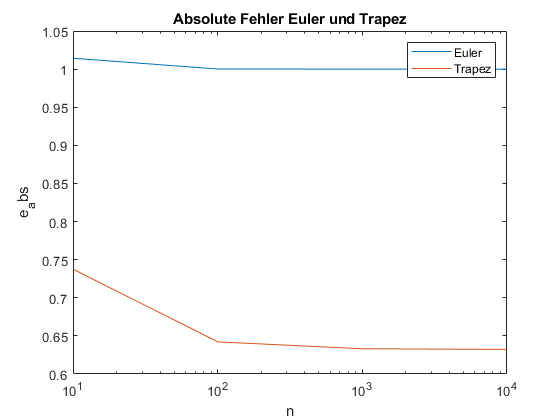

three_one_six; %3.1.6

Im Diagramm ist zu sehen dass der absolute Fehler des Verfahrens mit der Trapezregel schneller pro Iteration sinkt als beim Euler-Verfahren. Folglich konvergiert das Verfahren mit der Trapezregel schneller als das Euler-Verfahren.

### `3.1.7 Testen der Routine`

`-`

## `3.2 Anwendung`

### `3.2.1 Gleichung als System der Form`


$$\begin{array}{l}
y^{\prime } =f_{\textrm{chem}} \left(t,y\right)\\
\;\;\;=\left\lbrack \begin{array}{ccc}
-0\ldotp 04 & 0 & {10}^4 y_2 \\
0\ldotp 04 & -3\cdot 10{\;}^7 \;y_2  & -{10}^4 y_2 \\
0 & 3\cdot {10}^7 y_2  & 0
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 
\end{array}\right\rbrack \textrm{mit}\;y\left(0\right)=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack 
\end{array}$$


### `3.2.2 Routine [t,dy] = f_chem(t,y)`

`Siehe `f_chem.m``

### `3.2.3 Jacobi-Matrix `$D_y f_{\textrm{chem}} \left(t,y\right)$


$$J=\left\lbrack \begin{array}{ccc}
-0\ldotp 04 & {10}^{4\;} y_3  & 10{\;}^4 y_2 \\
0\ldotp 04 & -6\cdot {10}^7 y_2 -{10}^4 \;y_3  & -{10}^4 y_2 \\
0 & 6\cdot {10}^7 y_2  & 0
\end{array}\right\rbrack$$


### `3.2.4 Routine J = f_chem_jac(t,y)`

`Siehe `f_chem_jac.m``

### `3.2.5 & 3.2.6 Lösung des Anfangswertproblems und Performanz`

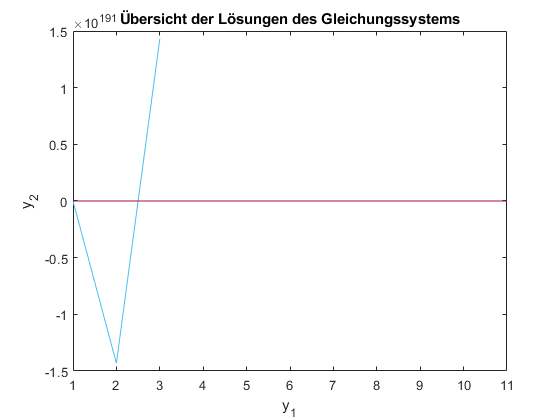

solving_f_chem;

Die Werte der verschiedenen Ansätze zur Lösung des Anfangswertproblems laufen leider stark auseinander. Die Werte für die impliziten Verfahren - im Diagramm rot dargestellt -  verbleiben mit steigenden Schrittzahlen nahe bei 0 wobei die Werte der expliziten Verfahren - im Diagramm in blau dargestellt - sehr schnell gegen das negative und danach gegen das positive Unendliche gehen. Der Fehler konnte in der zur nutzbaren Zeit nicht gefunden werden.

## 4. Zeitaufgelöste Simulation - Bearbeiter_in A und B

In diesem Abschnitt arbeiten wir mit der ursprünglichen Gleichung (9) und den Grenzen (10.1 und 10.2). 


$$\begin{array}{l}
\frac{\delta u}{\delta t}\left(t,z_i \right)=D\frac{\delta^2 u}{\delta z^2 }\left(t,z_i \right)-\left(k_1 +k_2 N_D \right)u\left(t,z_i \right)\;,\;\left(9\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;t\ge 0\;,\;i=0,1,\ldotp \ldotp \ldotp ,N\\
\frac{\delta u}{\delta z}\left(t,0\right)=S_L \left(t,0\right)\;\;\left(10\ldotp 1\right)\;\;\;\frac{\delta u}{\delta z}\left(t,d\right)=S_R \left(t,d\right)\;\;\left(\;10\ldotp 2\right)\;\;t\ge 0
\end{array}$$


### Bearbeiter_in A

#### zu 4.1 Formulieren Sie das System in der Form $u^{\prime } =F\left(t,u\right)$

Wir stellen diesmal nach $\frac{\delta u}{\delta t}$ um und approximieren wieder unser $\frac{\delta^2 u}{\delta z^2 }$


$$\begin{array}{l}
{\dot{u} }_i \left(t\right)=D\left(\frac{u_{i+1} \left(t\right)-2u_i \left(t\right)+u_{i-1} \left(t\right)}{h^2 }\right)-ku_i \left(t\right)-k_2 u_i^2 \left(t\right)+S_i \left(t\right)\\
{\dot{u} }_i \left(t\right)=\frac{D}{h^2 }\left\lbrack u_{i+1} \left(t\right)-2u_i \left(t\right)+u_{i-1} \left(t\right)-\left(\frac{{\textrm{kh}}^2 }{D}\right)u_i \left(t\right)-\left(\frac{k_2 h^2 }{D}\right)u_i^2 \left(t\right)+\left(\frac{h^2 }{D}\right)S_i \left(t\right)\right\rbrack 
\end{array}$$


Damit haben wir unsere allgemeine Formel für die inneren Knoten. Das $\frac{D}{h^2 }$ klammern wir später aus dem Vektor bzw. Jacobi-Matrix aus.

Wir bestimmen nun unsere Grenzwerte wieder. Die sich bis auf die Abhängigkeit von t nicht weiter ändern. 


$$\begin{array}{l}
\frac{u_1 \left(t\right)-u_{-1} \left(t\right)}{2h}=\frac{S_L u_0 \left(t\right)}{D}\\
u_1 \left(t\right)-u_{-1} \left(t\right)=\frac{2hS_L u_0 \left(t\right)}{D}\\
u_{-1} \left(t\right)=-\frac{2hS_L u_0 \left(t\right)}{D}+u_1 \left(t\right)
\end{array}$$
                    
$$\begin{array}{l}
\frac{u_{N+1} \left(t\right)-u_{N-1} \left(t\right)}{2h}=-\frac{S_R {\;u}_N \left(t\right)}{D}\\
u_{N+1} \left(t\right)-u_{N-1} \left(t\right)=-\frac{2h\;S_R \;u_N \left(t\right)}{D}\\
u_{N+1} \left(t\right)=-\frac{2h{\;S}_R \;u_N \left(t\right)}{D}+u_{N-1} \left(t\right)
\end{array}$$


Diese können wir wieder für unsere allgemeine Gleichung mit  i=0 und i=N einsetzen und erhalten die linke bzw. rechte Grenze.


$$\begin{array}{l}
i=0\\
{\dot{u} }_0 \left(t\right)=\frac{D}{h^2 }\left\lbrack u_1 \left(t\right)-2u_0 \left(t\right)+u_{-1} \left(t\right)-\left(\frac{{\textrm{kh}}^2 }{D}\right)u_0 \left(t\right)-\left(\frac{k_2 h^2 }{D}\right)u_0^2 \left(t\right)+\left(\frac{h^2 }{D}\right)S_0 \left(t\right)\right\rbrack \\
{\dot{u} }_0 \left(t\right)=\frac{D}{h^2 }\left\lbrack u_1 \left(t\right)-2u_0 \left(t\right)-\frac{2hS_L u_0 \left(t\right)}{D}+u_1 \left(t\right)-\left(\frac{{\textrm{kh}}^2 }{D}\right)u_0 \left(t\right)-\left(\frac{k_2 h^2 }{D}\right)u_0^2 \left(t\right)+\left(\frac{h^2 }{D}\right)S_0 \left(t\right)\right\rbrack \\
{\dot{u} }_0 \left(t\right)=\frac{D}{h^2 }\left\lbrack {2u}_1 \left(t\right)-\left(\frac{2hS_L }{D}+2+\frac{{\textrm{kh}}^2 }{D}\right)u_0 \left(t\right)-\left(\frac{k_2 h^2 }{D}\right)u_0^2 \left(t\right)+\left(\frac{h^2 }{D}\right)S_0 \left(t\right)\right\rbrack 
\end{array}$$



$$\begin{array}{l}
i=n\\
{\dot{u} }_N \left(t\right)=\frac{D}{h^2 }\left\lbrack u_{N+1} \left(t\right)-2u_N \left(t\right)+u_{N-1} \left(t\right)-\left(\frac{{\textrm{kh}}^2 }{D}\right)u_N \left(t\right)-\left(\frac{k_2 h^2 }{D}\right)u_N^2 \left(t\right)+\left(\frac{h^2 }{D}\right)S_N \left(t\right)\right\rbrack \\
{\dot{u} }_N \left(t\right)=\frac{D}{h^2 }\left\lbrack -\frac{2hS_R u_0 \left(t\right)}{D}-2u_N \left(t\right)-2u_{N-1} \left(t\right)-\left(\frac{{\textrm{kh}}^2 }{D}\right)u_N \left(t\right)-\left(\frac{k_2 h^2 }{D}\right)u_N^2 \left(t\right)+\left(\frac{h^2 }{D}\right)S_N \left(t\right)\right\rbrack \\
{\dot{u} }_N \left(t\right)=\frac{D}{h^2 }\left\lbrack {2u}_{N-1} \left(t\right)-\left(\frac{2hS_R }{D}+2+\frac{{\textrm{kh}}^2 }{D}\right)u_N \left(t\right)-\left(\frac{k_2 h^2 }{D}\right)u_N^2 \left(t\right)+\left(\frac{h^2 }{D}\right)S_N \left(t\right)\right\rbrack 
\end{array}$$


Darüberhinaus entwickeln wir noch eine Gleichung für i=1 wobei wir aus den bisherigen Erfahrungen bereits die generalisierung für die inneren Knoten ableiten können.


$$\begin{array}{l}
i=1\\
{\dot{u} }_1 \left(t\right)=\frac{D}{h^2 }\left\lbrack u_2 \left(t\right)-2u_1 \left(t\right)+u_0 \left(t\right)-\left(\frac{{\textrm{kh}}^2 }{D}\right)u_1 \left(t\right)-\left(\frac{k_2 h^2 }{D}\right)u_1^2 \left(t\right)+\left(\frac{h^2 }{D}\right)S_1 \left(t\right)\right\rbrack \\
{\dot{u} }_1 \left(t\right)=\frac{D}{h^2 }\left\lbrack u_1 \left(t\right)-\left(2+\frac{{\textrm{kh}}^2 }{D}\right)u_1 \left(t\right)-\left(\frac{k_2 h^2 }{D}\right)u_1^2 \left(t\right)+\left(\frac{h^2 }{D}\right)S_1 \left(t\right)\right\rbrack 
\end{array}$$


Zur Übersichtlichkeit nutzen wir wieder Variablen um wiederkehrende Information abzuspeichen und eine übersichtlichen Vektor F(t,u) zu bekommen

$L=\frac{2hS_L }{D}+2+\frac{{\textrm{kh}}^2 }{D}$   , $b=\frac{k_2 h^2 }{D}$    , $c=2+\frac{{\textrm{kh}}^2 }{D}$ , $R=\frac{2hS_L }{D}+2+\frac{{\textrm{kh}}^2 }{D}$ 

Daraus ergibt sich:


$$\overset{F\left(t,u\right)}{\frac{D}{h^2 }\left\lbrack \begin{array}{c}
-\left(L\right)u_0 \left(t\right)-\left(b\right)u_0^2 \left(t\right)+2u_1 \left(t\right)+\left(\frac{h^2 }{D}\right)S_0 \left(t\right)\\
1u_0 \left(t\right)-\left(c\right)u_1 \left(t\right)-\left(b\right)u_1^2 \left(t\right)+1u_2 \left(t\right)+\left(\frac{h^2 }{D}\right)S_1 \left(t\right)\\
1u_{i-1} \left(t\right)-\left(c\right)u_i \left(t\right)-\left(b\right)u_i^2 \left(t\right)+1u_{i+1} \left(t\right)+\left(\frac{h^2 }{D}\right)S_i \left(t\right)\\
1u_{N-2} \left(t\right)-\left(c\right)u_{N-1} \left(t\right)-\left(b\right)u_{N-1}^2 \left(t\right)+1u_N \left(t\right)+\left(\frac{h^2 }{D}\right)S_{N-1} \left(t\right)\\
2u_{N-1} \left(t\right)-\left(R\right)u_N \left(t\right)-\left(b\right)u_N^2 \left(t\right)+\left(\frac{h^2 }{D}\right)S_N \left(t\right)
\end{array}\right\rbrack ={\dot{u} }_i \left(t\right)}$$


Wichtig ist, das $\frac{D}{h^2 }$ nicht vergessen wird.

Da wir in der nächsten Aufgabe Routinen zur Berechnung von F(t,u) und DF(t,u) bereistellen, stellen wir hier auch gleich die Jacobi-Matrix auf.


$$\overset{\textrm{DF}\left(t,u\right)}{\frac{D}{h^2 }\left\lbrack \begin{array}{cccccc}
-\left(L\right)-2\left(b\right)u_0 \left(t\right) & 2 & 0 & 0 & 0 & 0\\
1 & -c-2\left(b\right)u_1 \left(t\right) & 1 & 0 & 0 & 0\\
0 & 1 & -c-2\left(b\right)u_2 \left(t\right) & 1 & 0 & 0\\
0 & 0 & 1 & -c-2\left(b\right)u_i \left(t\right) & 1 & 0\\
0 & 0 & 0 & 1 & -c-2\left(b\right)u_{N-1} \left(t\right) & 1\\
0 & 0 & 0 & 0 & 2 & -\left(R\right)-2\left(b\right)u_N \left(t\right)
\end{array}\right\rbrack }$$


#### zu 4.2 Routine f**d_nonlintime(t,u) und fd_nonlintime_jac(t,u)**

In diesem letzte Teilbereich des Bearbeiter B werden nun die Routinen  F(t,u) und DF(t,u) entwickelt. 

**zu fd_nonlintime und fd_nonlintime_jac**

Um eine parallele Arbeit zu ermöglichen wurden in diesem Fall die Parameter in die Funktion geschrieben und auch die benötigte Zeitfunktion s(t,z) mit hinein implementiert. In diesem Fall gibt es nur noch die globale Variable S0, welche dann durch Bearbeiter verändert werden kann um es entsprechend der Aufgabenstellung S0 anzupassen. 

Beide Routinen bekommen eine Zeitfunktion. Jedoch verschwindet der S(z,t) Term durch die partielle Ableitung in der Jacobi-Matrix. Wodurch praktisch eine Eingabe eines t unwichtig ist, jedoch zu einfacheren Integrierung durch Bearbeiter_in B noch in der Routine steht.

### Bearbeiter_in B

## `4.3 Implizite Trapezregel & 4.4 Ergebnis im Mesh`

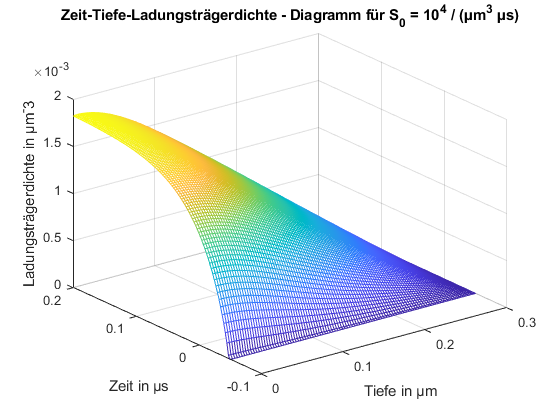

tol = 1e-6;
n = 1e2; 
tspan = [-0.05, 0.2];
y0 = zeros(n + 1);
nmax = Inf;

ass4_mesh_plot_1e4(tspan, y0, n, tol, nmax);

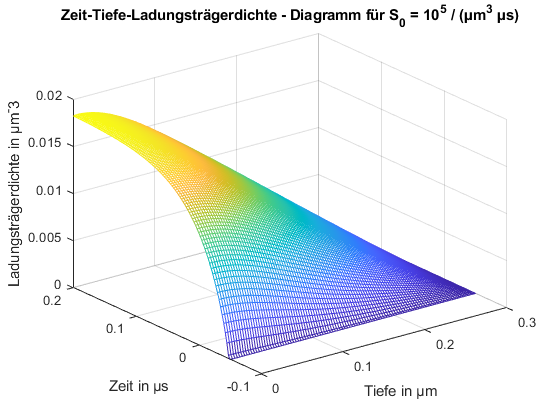

ass4_mesh_plot_1e5(tspan, y0, n, tol, nmax);

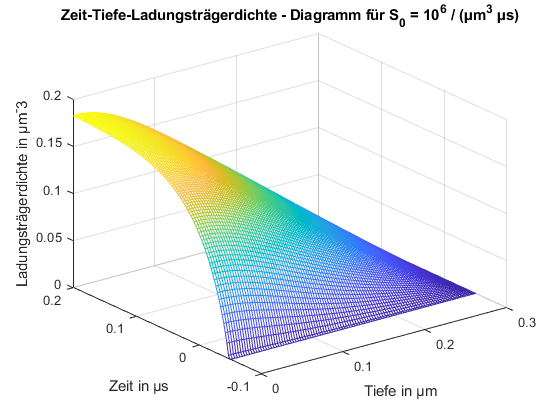

ass4_mesh_plot_1e6(tspan, y0, n, tol, nmax);

In dem Graphen erkennt man gut die Entwicklung der Ladungsträgerdichte u(t,z). Mit steigender Zeit nimmt u zu, jedoch fällt sie auch mit zunehmender Stärke wieder ab. 

Umso stärker der Laserbeschuss und somit umso größer S0 umso größer skalliert  die Ladungsträgerdichte. 

%% Benötigte Funktionen für 2.1.7 und 2.2.5 und 4.3/4

function mesh_plot_ass4(sol_values, n, title_to_show)
    mesh(linspace(0, 0.3, n + 1)', linspace(-.05, .2, n + 1)', sol_values);
    title(title_to_show)
    xlabel("Tiefe in µm")
    ylabel("Zeit in µs")
    zlabel("Ladungsträgerdichte in µm^-3")
end

function ass4_mesh_plot_1e4(tspan, y0, n, tol, nmax)
    global S0;
    S0 = 1e4;
    [~, sol_values] = impl_trapez(@fd_nonlintime, tspan, y0, n, @fd_nonlintime_jac, tol, nmax);
    mesh_plot_ass4(sol_values, n, "Zeit-Tiefe-Ladungsträgerdichte - Diagramm für S_0 = 10^4 / (µm^3 µs)");
end

function ass4_mesh_plot_1e5(tspan, y0, n, tol, nmax)
    global S0;
    S0 = 1e5;
    [~, sol_values] = impl_trapez(@fd_nonlintime, tspan, y0, n, @fd_nonlintime_jac, tol, nmax);
    mesh_plot_ass4(sol_values, n, "Zeit-Tiefe-Ladungsträgerdichte - Diagramm für S_0 = 10^5 / (µm^3 µs)");
end

function ass4_mesh_plot_1e6(tspan, y0, n, tol, nmax)
    global S0;
    S0 = 1e6;
    [~, sol_values] = impl_trapez(@fd_nonlintime, tspan, y0, n, @fd_nonlintime_jac, tol, nmax);
    mesh_plot_ass4(sol_values, n, "Zeit-Tiefe-Ladungsträgerdichte - Diagramm für S_0 = 10^6 / (µm^3 µs)");
end

% Benötigte Funktionen für 2.1.7 und 2.2.5
function [sz] = s_test_nonlin(z)
    sz = 50.*z.^8+40.*z.^5+120.*z.^4-112.*z.^2+48.*z+70;
end

% u entspricht der ausgedachten Funktion
function uz = u(z)
    uz = 5.*z.^4+2.*z+5;
end


function [sz] = s_test_lin(z)
    sz = 20.*z.^4-120.*z.^2+8.*z+20;
end